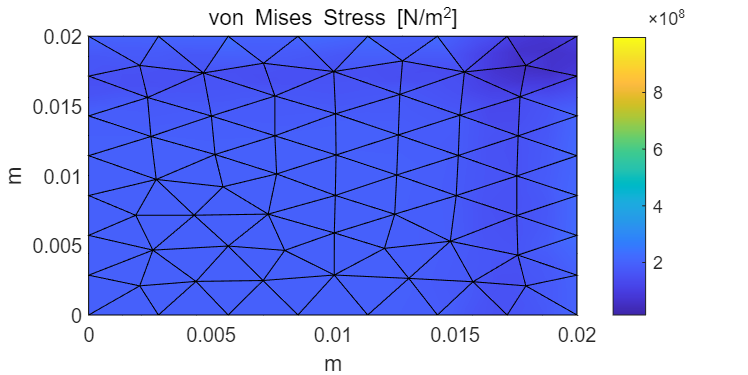

% Determine which elements are on the surfaces
stressType = 4; % See ExtractStress.m

TwoDElementsOnSurf = [ElementsInDomain(MeshFile, order, 2, 1);
    ElementsInDomain(MeshFile, order, 2, 3);
    ElementsInDomain(MeshFile, order, 2, 4);
    ElementsInDomain(MeshFile, order, 2, 5);
    ElementsInDomain(MeshFile, order, 2, 6);
    ElementsInDomain(MeshFile, order, 2, 7);
    ElementsInDomain(MeshFile, order, 2, 8);
    ElementsInDomain(MeshFile, order, 2, 9);
    ElementsInDomain(MeshFile, order, 2, 10);
    ElementsInDomain(MeshFile, order, 2, 11)];

if order == 2
    AllNodes = [1 5 2 6 3 7;
        2 6 3 9 4 10;
        3 9 4 8 1 7;
        4 8 1 5 2 10];
elseif order == 1
    AllNodes = [1 2 3; 2 3 4; 3 4 1; 4 1 2];
end

% Obtain the shape functions and their derivatives
[N,N_g,N_h,N_r] = shape_functions(order);
N_ = @(g,h,r) [N_g(g,h,r),N_h(g,h,r),N_r(g,h,r)]';

% The Jacobian matrix.
J = @(xyz,g,h,r) N_(g,h,r)*xyz;

% Parametric positions of TwoDElmts
ParaPosi = [0,0,0;
    1,0,0;
    0,1,0;
    0,0,1;
    .5,0,0;
    .5,.5,0;
    0,.5,0;
    0,0,.5;
    0,.5,.5;
    .5,0,.5];



figure
set(gcf,'unit','centimeters','position',[0,0,40,20])
hold on
for d = 1:2
    E      = properties(1,d);
    nu     = properties(2,d);
    alphaT = properties(3,d)*(properties(5,d) - properties(4,d));
    strain_th = alphaT * [ones(3,1); zeros(3,1)];
    E_m = Obtian_E_m(E,nu);
    E_th = E_m*strain_th;

    Elements = ElementsInDomain(MeshFile, order, 3, d);
    Be = zeros(6,3*size(Elements,2));
    NElements = length(Elements);

    % Determine elements with one side on surfaces
    Tag_ElmtOnSurf = zeros(NElements,1);
    CountElmtOnSurf = 0;
    for i = 1:NElements
        if ifElmtOnSurf(Elements(i,:),TwoDElementsOnSurf) == 1
            CountElmtOnSurf = CountElmtOnSurf + 1;
            Tag_ElmtOnSurf(CountElmtOnSurf) = i;
        end
    end
    Tag_ElmtOnSurf = Tag_ElmtOnSurf(1:CountElmtOnSurf);
    
    % Plot the triangle for each element
    for i = 1:CountElmtOnSurf
        NodesInElement = Elements(Tag_ElmtOnSurf(i),:);
        % Extract nodal displacements
        u = zeros(3*size(Elements,2),1);
        u(1:3:end) = U(3*NodesInElement-2);
        u(2:3:end) = U(3*NodesInElement-1);
        u(3:3:end) = U(3*NodesInElement);

        XYZ = Nodes(NodesInElement,:);
        Je = @(g,h,r) J(XYZ,g,h,r); % The Jacobian matrix for this element
        % Determine which sides are on surface
        FirstFourNodes = [NodesInElement(1:4) NodesInElement(1:4)];
        
        for j = 1:4
            if ifTriangleOnSurf(FirstFourNodes(j:j+2),TwoDElementsOnSurf) == 1

                % Calculate strain at side nodes
                SurfElmtSequence = AllNodes(j,:);
                stress = zeros(length(SurfElmtSequence),1);

                for k = 1:length(SurfElmtSequence)
                    ParaPosition = ParaPosi(SurfElmtSequence(k),:);
                    g = ParaPosition(1); h = ParaPosition(2); r = ParaPosition(3);
                    Jacobian = Je(g,h,r);
                    B = Jacobian \ N_(g,h,r);

                    Be(1,1:3:end) = B(1,:);
                    Be(4,2:3:end) = B(1,:);
                    Be(6,3:3:end) = B(1,:);
                    Be(2,2:3:end) = B(2,:);
                    Be(4,1:3:end) = B(2,:);
                    Be(5,3:3:end) = B(2,:);
                    Be(3,3:3:end) = B(3,:);
                    Be(5,2:3:end) = B(3,:);
                    Be(6,1:3:end) = B(3,:);

                    strain = Be * u;

                    % Elastic strain
                    strain_el = strain - strain_th;

                    % NodalStress 
                    NodalStress = E_m * strain_el;
                    stress(k) = ExtractStress(NodalStress,stressType);
                end
                
                % Plot the triangle
                fill3(XYZ(SurfElmtSequence,1),XYZ(SurfElmtSequence,2),XYZ(SurfElmtSequence,3),stress)

            end
        end
    end
end
% colormap(jet)
colorbar
% caxis([0.1,2.8]*10^8)
xlabel('m')
ylabel('m')
zlabel('m')
title('von Mises Stress [N/m^2]')
hold off